This script is used to generate the figures used in the following manuscript:

Figure 1.

Figure 2.

Figure 3.

Figure 4.

Figure 5. 

%% pulling the data back out
Figure5_data = nwbRead("Figure5_ProcessedData.nwb",'ignorecache');
%%
name_data = [ ...
    "time_span", ...
    "accuracy_per_ROI", ...
    "accuracy_per_ROI_sh", ...
    "accuracy_per_ROI_pre", ...
    "accuracy_per_ROI_sh_pre", ...
    "latency_per_ROI", ...
    "mean_accuracy", ...
    "mean_accuracy_indexing", ...
    ];
name_ROI = [ ...
    "ROI_1", ...
    "ROI_2", ...
    "ROI_5", ...
    "ROI_15", ...
    "ROI_2000", ...
    ];
FigureFive = struct;
pastend = zeros([70,5]);

for rnum = 1:size(name_ROI,2) %for all the ROIs
    for ct = 1:70 %for all the sessions
        for pik = 1:size(name_data,2)-1 %for all the datasets within
            %assigning dynamic names
            if ct < 10
                name_session = append("session_0",num2str(ct));
            else
                name_session = append("session_",num2str(ct));
            end
            name_process = append(name_ROI(rnum),'_',name_data(pik));
            %pulling data from NWB file
            temp_table = Figure5_data.processing.get(char(name_process)).dynamictable.get(char(name_data(pik))).getRow(ct);
            %running throuhg a condition that if dataset = 7 the
            %processing is different
            if pik == size(name_data,2)-1
                %name of dataset wihtin the NWB file
                name_index = append(name_ROI(rnum),'_',name_data(pik+1));
                %pulling index points for a single session using NWB files
                temp_indexpoints = Figure5_data.processing.get(char(name_index)).dynamictable.get(char(name_data(pik+1))).getRow(ct);
                tamp_indexpoints = temp_indexpoints{:,:}{1,1};
                %accounting for the index offset after first session
                %pulling offset value
                time_index = Figure5_data.processing.get(char(name_process)).dynamictable.get(char(name_data(pik))).vectordata.get('col1_index').data(:);
                %putting data in correct format
                temp_table = temp_table{1,1}{:,:};
                %pulling the session ROI ending index values
                table_index = Figure5_data.processing.get(char(name_index)).dynamictable.get(char(name_data(pik+1))).getRow(ct); %ending index points for each sessions mean averages
                indexPoints = table_index{1,1}{:,:};
                %creating cell array for data
                average_cell = cell([size(indexPoints,1),1]);
                Round = 1;
                for ti = 1:size(indexPoints,1)
                    RoundEnd = indexPoints(ti);
                    average_cell{ti,1} = temp_table(Round:RoundEnd);
                    Round = RoundEnd + 1;
                end
                FigureFive.(name_session).(name_ROI(rnum)).(name_data(pik)) = cell2table(average_cell);
                FigureFive.(name_session).(name_ROI(rnum)).(name_data(pik)).Properties.VariableNames(1) = "mean_average";
            else
                FigureFive.(name_session).(name_ROI(rnum)).(name_data(pik)) = temp_table{:,:}{1,1}';
            end
            
        end
    end
end

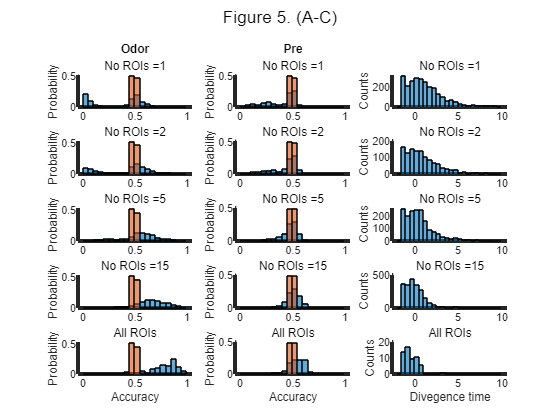

%{
Figure 5.A-C
A. Histogram for stimulus decoding accuracy calculated in the odor period (3.1 to 4.1 sec) for all proficient sessions (66 sessions) 
for 4 mice. i to v show the histogram for an increasing number of ROIs per decoding session. Blue is stimulus decoding accuracy, 
brown is stimulus decoding accuracy calculated after shuffling the labels. Histograms were normalized by dividing by the total 
number of counts.
B. Histograms calculated in the Pre period (-1 to 0 sec)
C. 
%}
%
%Plot accurcy histograms and do glm
glm_acc=[];
glm_acc_ii=0;
input_acc_data=[];
id_acc_ii=0;
%{
Setting constant values
%}
all_no_ROIs=[1 2 5 15 2000];
edges= 0:0.05:1;
loca_A = [1,4,7,10,13];
includeNum = 70;
epoch_labels{1}='Pre';
epoch_labels{2}='Odor';

figure();

for ii_ROI_choices=1:length(all_no_ROIs)

    subplot(length(all_no_ROIs),3,loca_A(ii_ROI_choices))
    ax=gca;
    ax.LineWidth=3;
    hold on

    all_accs=[];
    all_accs_sh=[];
    for fileNo=1:includeNum-1

        if fileNo < 10
            name_session = append("session_0",num2str(fileNo));
        else
            name_session = append("session_",num2str(fileNo));
        end
        this_time_span =FigureFive.(name_session).(name_ROI(ii_ROI_choices)).time_span;
        these_accs =FigureFive.(name_session).(name_ROI(ii_ROI_choices)).accuracy_per_ROI;
        these_accs_sh =FigureFive.(name_session).(name_ROI(ii_ROI_choices)).accuracy_per_ROI_sh;

        vetted_accs=[];
        ii_v=0;
        for ii_repeats=1:length(these_accs)
            %NOte: some of the noisy traces yield artifactual
            %accuracy above 0.5
            this_acc_time_course = FigureFive.(name_session).(name_ROI(ii_ROI_choices)).mean_accuracy.mean_average{ii_repeats}';

            if mean(this_acc_time_course(this_time_span<-2))<0.53
                ii_v=ii_v+1;
                vetted_accs(ii_v)=these_accs(ii_repeats);
                vetted_accs_sh(ii_v)=these_accs_sh(ii_repeats);
            end
        end
        if ~isempty(vetted_accs)
            all_accs=[all_accs vetted_accs];
            all_accs_sh=[all_accs_sh vetted_accs_sh];

            glm_acc.data(glm_acc_ii+1:glm_acc_ii+length(vetted_accs))=vetted_accs;
            glm_acc.ROI_group(glm_acc_ii+1:glm_acc_ii+length(vetted_accs))=ii_ROI_choices*ones(1,length(vetted_accs));
            glm_acc.epoch(glm_acc_ii+1:glm_acc_ii+length(vetted_accs))=0*ones(1,length(vetted_accs));
            glm_acc_ii=glm_acc_ii+length(vetted_accs);

            id_acc_ii=id_acc_ii+1;
            input_acc_data(id_acc_ii).data=vetted_accs;
            if ii_ROI_choices<length(all_no_ROIs)
                input_acc_data(id_acc_ii).description=[epoch_labels{1} ' ' num2str(all_no_ROIs(ii_ROI_choices)) ' ROIs'];
            else
                input_acc_data(id_acc_ii).description=[epoch_labels{1} ' all ROIs'];
            end
        end

    end

    histogram(all_accs,edges,'Normalization','Probability')
    histogram(all_accs_sh,edges,'Normalization','Probability')

    if ii_ROI_choices~=length(all_no_ROIs)
        if ii_ROI_choices == 1
            title('Odor')
        end
        subtitle(['No ROIs =' num2str(all_no_ROIs(ii_ROI_choices))])
    else
        subtitle('All ROIs')
    end
    if ii_ROI_choices==5
        xlabel('Accuracy')
    end
    ylabel('Probability')
    hold("off")
end

%Fig. 8B
edges=[0:0.05:1];
loca_B = [2,5,8,11,14];
for ii_ROI_choices=1:length(all_no_ROIs)
    subplot(length(all_no_ROIs),3,loca_B(ii_ROI_choices))
    ax=gca;ax.LineWidth=3;
    hold on
    all_accs=[];
    all_accs_sh=[];
    for fileNo=1:includeNum

        if fileNo < 10
            name_session = append("session_0",num2str(fileNo));
        else
            name_session = append("session_",num2str(fileNo));
        end
        this_time_span=FigureFive.(name_session).(name_ROI(ii_ROI_choices)).time_span;
        these_accs=FigureFive.(name_session).(name_ROI(ii_ROI_choices)).accuracy_per_ROI_pre;
        these_accs_sh=FigureFive.(name_session).(name_ROI(ii_ROI_choices)).accuracy_per_ROI_sh_pre;
        vetted_accs=[];
        ii_v=0;
        for ii_repeats=1:length(these_accs)
            %NOte: some of the noisy traces yield artifactual
            %accuracy above 0.5

            this_acc_time_course = FigureFive.(name_session).(name_ROI(ii_ROI_choices)).mean_accuracy.mean_average{ii_repeats}';
            if mean(this_acc_time_course(this_time_span<-2))<0.53
                ii_v=ii_v+1;
                vetted_accs(ii_v)=these_accs(ii_repeats);
                vetted_accs_sh(ii_v)=these_accs_sh(ii_repeats);
            end
        end
        if ~isempty(vetted_accs)
            all_accs=[all_accs vetted_accs];
            all_accs_sh=[all_accs_sh vetted_accs_sh];

            if ~isempty(vetted_accs)
                all_accs=[all_accs vetted_accs];
                all_accs_sh=[all_accs_sh vetted_accs_sh];

                glm_acc.data(glm_acc_ii+1:glm_acc_ii+length(vetted_accs))=vetted_accs;
                glm_acc.ROI_group(glm_acc_ii+1:glm_acc_ii+length(vetted_accs))=ii_ROI_choices*ones(1,length(vetted_accs));
                glm_acc.epoch(glm_acc_ii+1:glm_acc_ii+length(vetted_accs))=1*ones(1,length(vetted_accs));
                glm_acc_ii=glm_acc_ii+length(vetted_accs);

                id_acc_ii=id_acc_ii+1;
                input_acc_data(id_acc_ii).data=vetted_accs;
                  if ii_ROI_choices<length(all_no_ROIs)
                    input_acc_data(id_acc_ii).description=[epoch_labels{2} ' ' num2str(all_no_ROIs(ii_ROI_choices)) ' ROIs'];
                else
                    input_acc_data(id_acc_ii).description=[epoch_labels{2} ' all ROIs'];
                end
            end
        end

    end
    histogram(all_accs,edges,'Normalization','Probability')
    histogram(all_accs_sh,edges,'Normalization','Probability')

    if ii_ROI_choices~=length(all_no_ROIs)
        if ii_ROI_choices == 1
            title('Pre')
        end
        subtitle(['No ROIs =' num2str(all_no_ROIs(ii_ROI_choices))])
    else
        subtitle('All ROIs')
    end
    if ii_ROI_choices==5
        xlabel('Accuracy')
    end
    ylabel('Probability')
    hold("off")
end
%Fig. 8C
glm_lat=[];
glm_lat_ii=0;
input_lat_data=[];
id_lat_ii=0;
edges= -2:0.5:10 ;
loca_B = [3,6,9,12,15];
all_lats_per_ROI_choice=[];
for ii_ROI_choices=1:length(all_no_ROIs)
    subplot(length(all_no_ROIs),3,loca_B(ii_ROI_choices))
    ax=gca;ax.LineWidth=3;
    hold on

    all_lats=[];
    for fileNo=1:includeNum-1
        if fileNo < 10
            name_session = append("session_0",num2str(fileNo));
        else
            name_session = append("session_",num2str(fileNo));
        end
        these_lats = FigureFive.(name_session).(name_ROI(ii_ROI_choices)).latency_per_ROI;
        this_time_span = FigureFive.(name_session).(name_ROI(ii_ROI_choices)).time_span;

        vetted_lats=[];
        ii_v=0;
        for ii_repeats=1:length(these_lats)
            %NOte: some of the noisy traces yield artifactual
            %accuracy above 0.5
            this_acc_time_course = FigureFive.(name_session).(name_ROI(ii_ROI_choices)).mean_accuracy.mean_average{ii_repeats}';

            if (mean(this_acc_time_course(this_time_span<-2))<0.53)&(~isnan(these_lats(ii_repeats)))
                ii_v=ii_v+1;
                vetted_lats(ii_v)=these_lats(ii_repeats);
            end
        end
        if ~isempty(vetted_lats)
            all_lats=[all_lats vetted_lats];


            glm_lat.data(glm_lat_ii+1:glm_lat_ii+length(vetted_lats))=vetted_lats;
            glm_lat.ROI_group(glm_lat_ii+1:glm_lat_ii+length(vetted_lats))=ii_ROI_choices*ones(1,length(vetted_lats));
            glm_lat_ii=glm_lat_ii+length(vetted_lats);

            id_lat_ii=id_lat_ii+1;
            input_lat_data(id_lat_ii).data=vetted_lats;
            if ii_ROI_choices<length(all_no_ROIs)
                input_lat_data(id_lat_ii).description=[num2str(all_no_ROIs(ii_ROI_choices)) ' ROIs'];
            else
                input_lat_data(id_lat_ii).description= 'all ROIs' ;
            end

        end
    end
  
    histogram(all_lats,edges)


    if ii_ROI_choices~=length(all_no_ROIs)
        subtitle(['No ROIs =', num2str(all_no_ROIs(ii_ROI_choices))])
    else
        subtitle('All ROIs')
    end
    if ii_ROI_choices==5
        xlabel('Divegence time')
    end
    ylabel('Counts')
    hold("off")
end

sgtitle('Figure 5. (A-C)')
hold off

Figure 5.D

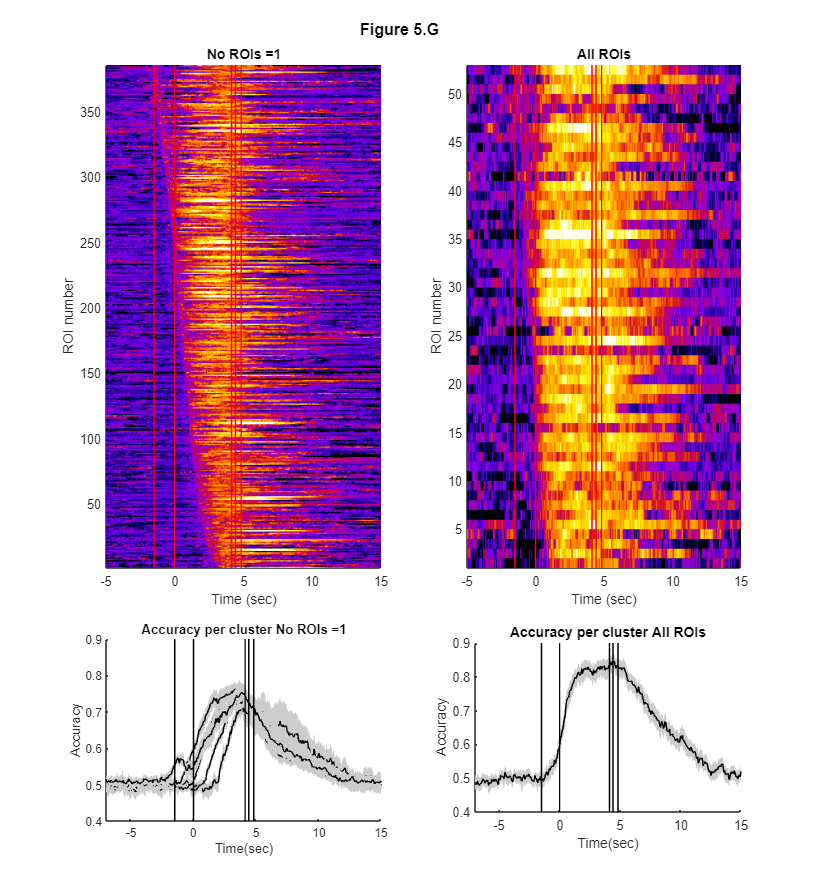

%{
Figure 5.D
(i). Time courses for decoding accuracies calculated with one ROI per session that reach at least 0.65 after 
trial start. 
(ii) Mean accuracy time courses calculated for one ROI accuracy time courses shown in Di with 
accuracy increase onsets in the following time windows: -1.5 to -1, -1 to 0, 0 to 1, 1 to 2, 2 to 3, >3 sec. 
(iii) Time courses for decoding accuracies calculated all ROIs per session. 
(iv) Mean accuracy time course for the time courses shown in Diii
%}
hFig = figure();
hFig.Position(1) = hFig.Position(1) + 350;
hFig.Position(2) = hFig.Position(2) + 550;
hFig.Position(3) = hFig.Position(3) + 350;
hFig.Position(4) = hFig.Position(4) + 550;

% Time events of interest (e.g. stimulus onset/offset, cues etc.)
% They are marked on the plots with vertical lines
delta_odor=4.127634e+00;
delta_odor_on_reinf_on=4.415787e+00;
delta_reinf=4.078266e-01;
timeEvents = [-1.5 0 delta_odor delta_odor_on_reinf_on delta_reinf+delta_odor_on_reinf_on];
acc_thr=[0.35 0.65];
cluster_times=[-1.5 -1;-1 0; 0 1; 1 2; 2 3; 3 200];
%Plot the pseudocolor time courses

time_span = FigureFive.session_01.ROI_1.time_span; 



subplot(4,2,1:2)
text(.4,.5,'Figure 5.G','FontSize',12,'FontWeight','bold'); axis off
ax = gca;
ax.Position(2) = ax.Position(2) + 0.12;

for ii_ROI_choices=1:length(all_no_ROIs)

    all_acc_time_courses=zeros(5000,length(time_span));
    all_acc_time_courses2=zeros(5000,length(time_span));
    all_lats_for_acc_time_courses=[];
    ii_included=0;
    for fileNo=1:includeNum-1

        if fileNo < 10
            name_session = append("session_0",num2str(fileNo));
        else
            name_session = append("session_",num2str(fileNo));
        end
        these_accs=FigureFive.(name_session).(name_ROI(ii_ROI_choices)).accuracy_per_ROI;
        these_lats=FigureFive.(name_session).(name_ROI(ii_ROI_choices)).latency_per_ROI;


        for ii_repeats=1:length(these_accs)
            if these_accs(ii_repeats)>=acc_thr(2)

                this_time_span = FigureFive.(name_session).(name_ROI(ii_ROI_choices)).time_span;
                this_acc_time_course = FigureFive.(name_session).(name_ROI(ii_ROI_choices)).mean_accuracy.mean_average{ii_repeats}';


                %NOte: some of the noisy traces yield artifactual
                %accuracy above 0.5
                if mean(this_acc_time_course(this_time_span<-2))<0.53
                    ii_included=ii_included+1;
                    all_lats_for_acc_time_courses(ii_included)=these_lats(ii_repeats);

                    resample=0;
                    if length(this_time_span)~=length(time_span)
                        resample=1;
                    else
                        if sum(time_span==this_time_span)~=length(time_span)
                            resample=1;
                        end
                    end
                    if resample==0
                        all_acc_time_courses(ii_included,:) = FigureFive.(name_session).(name_ROI(ii_ROI_choices)).mean_accuracy.mean_average{ii_repeats}';

                    else
                        %Resample
                        for ii_t=1:length(time_span)
                            if time_span(ii_t)<this_time_span(1)
                                all_acc_time_courses(ii_included,ii_t) = FigureFive.(name_session).(name_ROI(ii_ROI_choices)).mean_accuracy.mean_average{ii_repeats}(1);

                            else
                                if time_span(ii_t)>this_time_span(end)
                                    all_acc_time_courses(ii_included,ii_t) = FigureFive.(name_session).(name_ROI(ii_ROI_choices)).mean_accuracy.mean_average{ii_repeats}(end);

                                else
                                    if isempty(find(time_span(ii_t)==this_time_span))
                                        ii_before=find(this_time_span<time_span(ii_t),1,'last');
                                        ii_after=find(this_time_span>time_span(ii_t),1,'first');

                                        acc_before = FigureFive.(name_session).(name_ROI(ii_ROI_choices)).mean_accuracy.mean_average{ii_repeats}(ii_before)';
                                        acc_after = FigureFive.(name_session).(name_ROI(ii_ROI_choices)).mean_accuracy.mean_average{ii_repeats,1}(ii_after)';


                                        all_acc_time_courses(ii_included,ii_t)= acc_before+(acc_after-acc_before)*(time_span(ii_t)-this_time_span(ii_before))/(this_time_span(ii_after)-this_time_span(ii_before));
                                    else
                                        ii_found=find(time_span(ii_t)==this_time_span,1,'first');

                                        all_acc_time_courses(ii_included,ii_t) = FigureFive.(name_session).(name_ROI(ii_ROI_choices)).mean_accuracy.mean_average{ii_repeats}(ii_found)';


                                    end
                                end
                            end
                        end
                    end
                end
            end
        end
    end
    all_acc_time_courses(ii_included+1:end,:)=[];


    %Sort by diverging time
    to_sort=[all_lats_for_acc_time_courses' [1:ii_included]'];
    sorted=sortrows(to_sort);
    outperm=sorted(:,2);



    clusters=[];
    for ii_tc=1:length(all_lats_for_acc_time_courses)
        for clus=1:size(cluster_times,1)
            if (all_lats_for_acc_time_courses(ii_tc)>=cluster_times(clus,1))&(all_lats_for_acc_time_courses(ii_tc)<=cluster_times(clus,2))
                clusters(ii_tc)=clus;
            end
        end
    end
    if ii_ROI_choices == 1 || ii_ROI_choices == 5
        %Plot timecourses for all accuracy time courses

        if ii_ROI_choices == 1
            subplot(4,2,[3,5])
        elseif ii_ROI_choices == 5
            subplot(4,2,[4,6])
            
        end

        sorted_handles_out.all_acc_time_courses=[];
        sorted_handles_out.clusters=[];
        for ii=1:ii_included
            sorted_handles_out.all_acc_time_courses(ii_included-ii+1,:)=all_acc_time_courses(outperm(ii),:);
            sorted_handles_out.clusters(ii_included-ii+1)=clusters(outperm(ii));
        end

        %pcolor does not show the first row
        pseudo_acc=zeros(size(sorted_handles_out.all_acc_time_courses,1)+1,size(sorted_handles_out.all_acc_time_courses,2));
        pseudo_acc(1:end-1,:)=sorted_handles_out.all_acc_time_courses;

        time_span_mat=repmat(time_span,ii_included+1,1);
        ROI_mat=repmat(1:ii_included+1,length(time_span),1)';

        pcolor(time_span_mat,ROI_mat,pseudo_acc)
        hold('on')


        shading flat
        clim([0.4,1])

        for ii_te=1:length(timeEvents)
            plot([timeEvents(ii_te) timeEvents(ii_te)],[0 ii_included],'-r')
        end

        xlim([-5 15])
        ylim([1 ii_included])
        if ii_ROI_choices~=length(all_no_ROIs)
            title(['No ROIs =' num2str(all_no_ROIs(ii_ROI_choices))])
        else
            title(['All ROIs'])
        end
        xlabel('Time (sec)')
        ylabel('ROI number')
        ax = gca;
        ax.Position(2) = ax.Position(2) + 0.02;
        ax.Position(4) = ax.Position(4) + 0.2;
        colormap fire
    end

    if ii_ROI_choices == 1
        %Plot the average timecourses per cluster

        hold('off')
        subplot(4,2,7)

        hold('on')
        for clus=max(clusters):-1:1
            %plot the accuracies
            this_cluster_acc=[];
            ii_inc=0;
            for ii=1:length(sorted_handles_out.clusters)
                if sorted_handles_out.clusters(ii)==clus
                    ii_inc=ii_inc+1;
                    this_cluster_acc(ii_inc,:)=sorted_handles_out.all_acc_time_courses(ii,:);
                end
            end

            if ii_inc>=5
                CIpv = bootci(1000, @mean, this_cluster_acc);
                meanpv=mean(this_cluster_acc,1);
                CIpv(1,:)=meanpv-CIpv(1,:);
                CIpv(2,:)=CIpv(2,:)-meanpv;


                [hlpvl, hppvl] = boundedline(time_span,mean(this_cluster_acc), CIpv','cmap',[0 0 0]);


            end

        end

        ylim([0.4 0.9])
        this_ylim=ylim;
        for ii_te=1:length(timeEvents)
            plot([timeEvents(ii_te) timeEvents(ii_te)],this_ylim,'-k')
        end

        xlim([-7 15])


        xlabel('Time(sec)')
        ylabel('Accuracy')
        ax = gca;
        ax.Position(2) = ax.Position(2) - 0.05;
        ax.Position(4) = ax.Position(4) + 0.05;
        title(['Accuracy per cluster No ROIs =' num2str(all_no_ROIs(ii_ROI_choices))])
    end
    %Plot average of all traces
    if ii_ROI_choices == 5

        hold('off')
        subplot(4,2,8)

        hold('on')

        CIpv = bootci(1000, @mean, sorted_handles_out.all_acc_time_courses);
        meanpv=mean(sorted_handles_out.all_acc_time_courses,1);
        CIpv(1,:)=meanpv-CIpv(1,:);
        CIpv(2,:)=CIpv(2,:)-meanpv;


        [hlpvl, hppvl] = boundedline(time_span,mean(sorted_handles_out.all_acc_time_courses), CIpv','cmap',[0 0 0]);
        ylim([0.4 0.9])
        this_ylim=ylim;
        for ii_te=1:length(timeEvents)
            plot([timeEvents(ii_te) timeEvents(ii_te)],this_ylim,'-k')
        end
        xlim([-7 15])
        xlabel('Time(sec)')
        ylabel('Accuracy')
        ax = gca;
        ax.OuterPosition(2) = ax.OuterPosition(2) - 0.05;
        ax.OuterPosition(4) = ax.OuterPosition(4) + 0.06;
        title('Accuracy per cluster All ROIs')
    end
end

Figure 6

Figure 7